# **Adaptive Short-Time Fourier Transform**

## Signal Definition

clc,clear
load SignalsTypes.mat Signals
s = Signals.S.HypChirps';
dt = Signals.S.dt;
N = length(s);

## Time-Frequency Transform

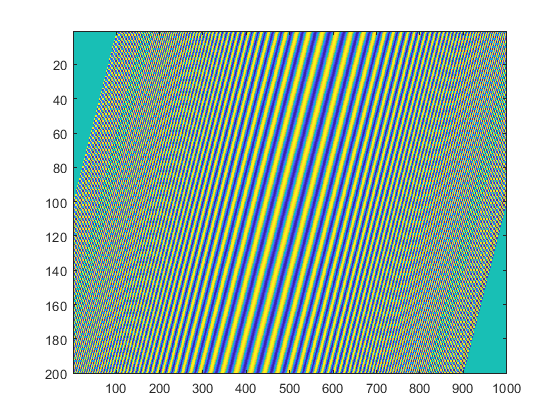

[ G, ~, ~, W, H ] = AdaptiveSTFT( s, 'simple');
imagesc(H)

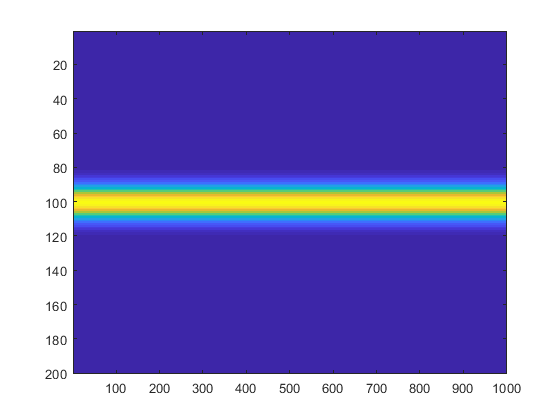

imagesc(W)

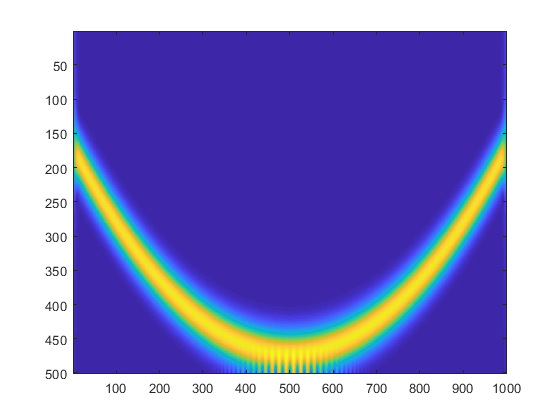

imagesc(G)

## Optimization

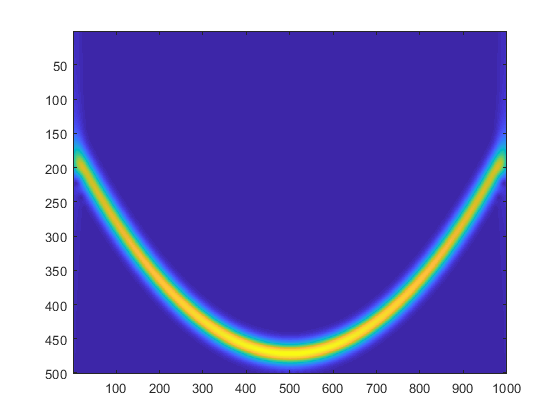

[ G, CF ] = AdaptiveSTFT( s, 'adaptive', 'pow2', 1 );
imagesc(G)

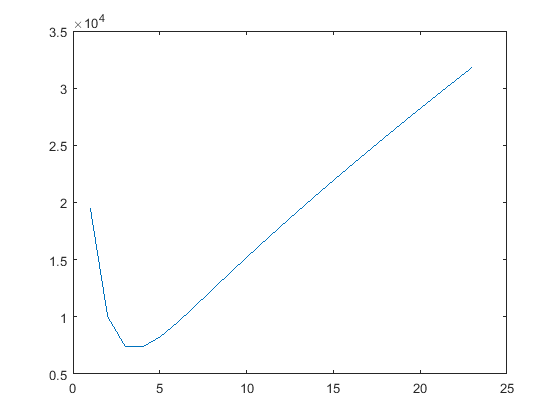

plot(CF)

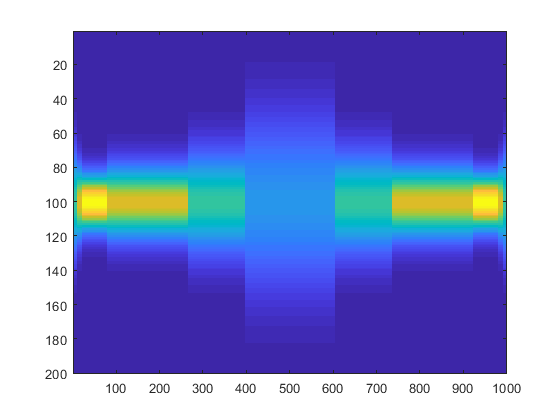

[ G, ~, P, W ] = AdaptiveSTFT( s, 'adaptive', 'pow2', 2 );
imagesc(W)

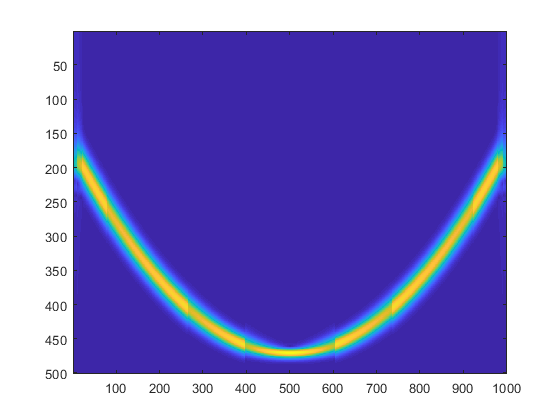

imagesc(G)

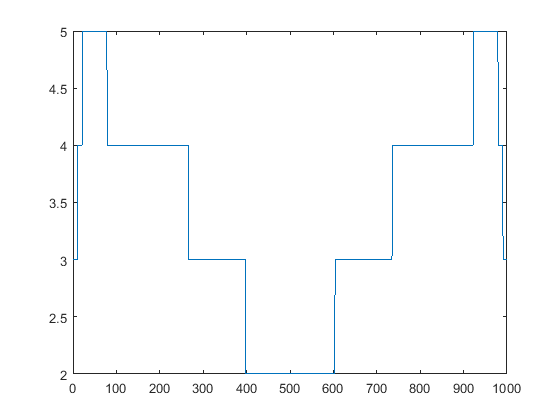

plot(P)